## Przetwarzanie i normalizacja danych

 Wyrównanie długości nagrań, normalizacja głośności, wycinanie fragmentów ciszy itp. 

load_data()
for k=1:length(data)
    data{k} = preprocess(data{k});
end

## Ekstrakcja wektora cech

 Moc sygnału w różnych częstotliwościach, bez normalizacji częstotliwości bazowej.

% % wyznacz jedną cechę do określenia rozmiaru wektora
% % zakładamy stały rozmiar wektora cech
tmp = extract(data{1}, fs);
feats = zeros(length(tmp), length(data));
% 
% % wyznaczenie cech dla wszystkich danych
for k=1:length(data)
    feats(:,k) = extract(data{k}, fs);
end

## Trening klasyfikatora

Podstawą treningu są wektory cech i etykiety danych trenujących. Wyjściem powinien być pewien model dostępnych klas. Zależnie od wybranego klasyfikatora może mieć on różną postać. W ramach przykładu przygotowane zostały dwa proste klasyfikatory: najbliższego sąsiada (1-NN) oraz geometryczny. Klasyfikator 1-NN nie potrzebuje żadnego dodatkowego przygotowania danych - zbiór treningowy jest jednocześnie uzwanany za model. W przypadku klasyfikatora geometrycznego dla każdej z klas wyznaczane są uśrednione wektory cech i to one są zwracane jako ostateczny model. 

[model1, labels1] = fit_knn(feats(:, train_ids), train_lbl);

## Test klasyfikatora k-NN

cls1 = predict_knn(feats(:, test_ids), model1, labels1, 28);

Wyznaczenie skuteczności (liczba poprawnych klasyfikacji):

cls_true = test_lbl;
acc1 = sum(cls1 == cls_true) / length(cls1)

acc1 = 0.4861

Wygenerowanie macierzy pomyłek:

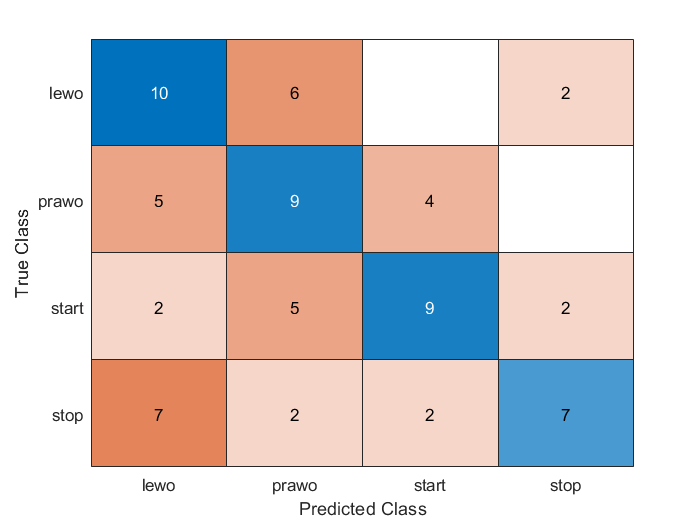

confusionchart(confusionmat(cls_true, cls1), names)

## Detekcja słów kluczowych w strumieniu

Dzieląc długie nagranie na (nakładające się) okna o ustalonej długości możemy każde z nich przepuścić przez wybrany klasyfikator. 


cls_all = [];
lbls_all = [];

for i = 1:23
    if i==9 || i==12 || i==22
else

name1 = sprintf("stream/%02d/stream_1.wav", i);
name2 = sprintf("stream/%02d/labels_1.txt", i);

% ważne założenie: nagranie ma takie samo Fs jak dane treningowe
stream = audioread(name1);

% zakładana długość i overlap słowa kluczowego (liczba próbek)
len = round(0.8 * fs);
overlap = round(0.1 * fs);

cls = zeros(length(stream), 1);
dst = zeros(length(stream), 1);

for k=1:overlap:length(stream)-len
    r = stream(k:k+len);
    r = preprocess(r, fs);
    f = extract(r, fs);
    [cls(k:k+len), dst(k:k+len)] = predict_knn(f, model1, labels1, 28);
%     [cls(k:k+len), dst(k:k+len)] = predict_geom(f, model1, labels1);
%     fit_geom
end

Klasyfikator zawsze daje jakąś odpowiedź, ale przyjmując pewne założenie dotyczące progu odległości możemy wyciąć predykcje niepewne:

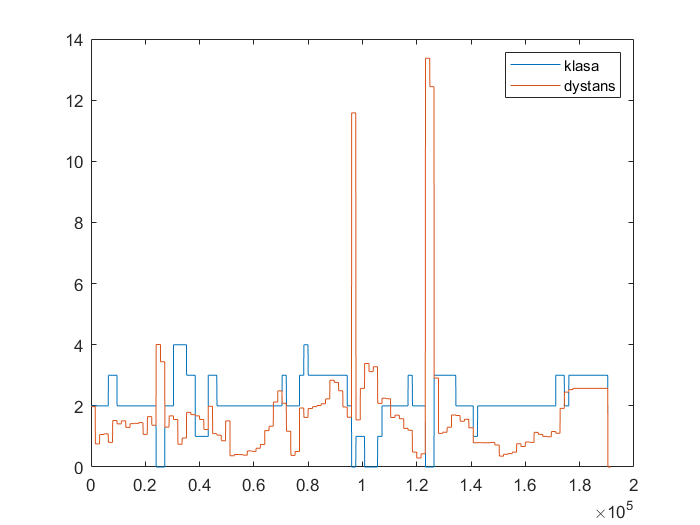

% figure; plot(cls); hold on; plot(dst); hold off; legend(["klasa", "dystans"]);
cls_filt = cls;
cls_filt(dst > 3) = 0;
figure; plot(cls_filt); hold on; plot(dst); hold off; legend(["klasa", "dystans"]);

## Analiza jakości detekcji

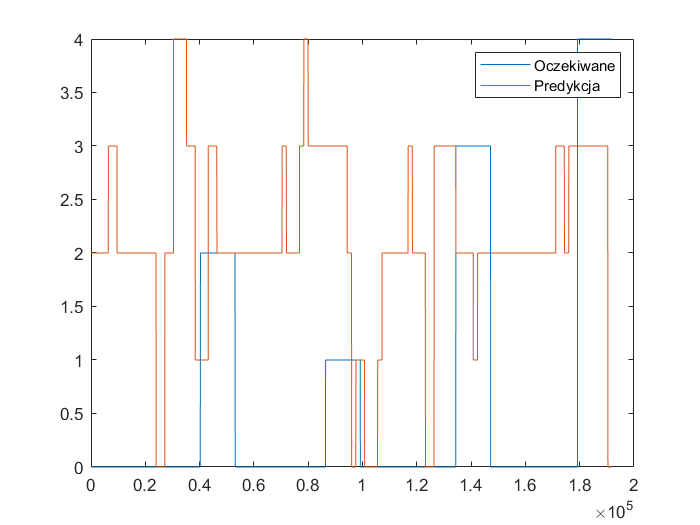

% wczytanie etykiet nagrania testowego
lbls = get_labels(name1, name2);
figure; plot(lbls); hold on; plot(cls_filt); legend("Oczekiwane", "Predykcja");


acc_1 = sum(lbls == 1 & cls_filt == 1) / sum(lbls == 1 | cls_filt == 1)

Matrix dimensions must agree.


cls_all = [cls_all cls_filt'];
lbls_all = [lbls_all lbls'];

jaccard(cls_filt, lbls);
    end
end


acc_3 = sum(lbls' == 1 & cls_filt' == 1) / sum(lbls' == 1 | cls_filt' == 1)
jaccard(cls_filt', lbls')

## Definicje funkcji

### Przetwarzanie wstępne

function y = preprocess(x, fs)
    y = x / max(x);
end

### Ekstrakcja wektora cech

function f = extract(x, fs)
    nfft = 256;
    f = pwelch(x, 1024, 256, nfft, fs);
    f = f / max(f);
end

### Klasyfikator k-NN

function [model, labels] = fit_knn(x, y)
    model = x;
    labels = y;
end

function [cls, dst] = predict_knn(feats, model, labels, k)
    % wyznacz wszystkie odległości pomiędzy wektorami cech feats a modelem
    dm = pdist2(feats', model', 'cityblock');
    
    % znajdź najmniejszą wartość dla każdego wiersza (próbki testowej)
    [dst_nn, min_idx] = mink(dm, k, 2);
    
    % określ klasę dla każdej próbki
    cls_nn = labels(min_idx);
    cls = mode(cls_nn, 2);
    for i=1:length(cls)
        inx = find(cls_nn(i,:)==cls(i));
        dst(i) = dst_nn(inx(1));

    end
    cls = cls';
    dst = dst';

end

### Pozostałe funkcje

function lbl = get_labels(stream, labels)
  M = containers.Map({'prawo', 'lewo', 'stop', 'start'}, [1 2 3 4]);

  [x, fs] = audioread(stream);
  lbl = zeros(size(x));
  
  fid = fopen(labels);
  txt = textscan(fid,'%s %f'); 
  
  for k=1:length(txt{2})
    ts = txt{2}(k) * fs;
    te = ts + 0.8 * fs;
    lbl(ts:te) = M(txt{1}{k});
  end
end

function f0 = pitchwin(x, fs, win)
    f_max = 300;
    lag_min = fs / f_max;
    f0 = zeros(floor((length(x)-win-1)/win), 1);
    for j=1:1:size(f0)
        i = 1 - win/2 + j * win;
        crop = x(i-win/2:i+win/2);
        [c, lags] = xcorr(crop, "normalized");
        c = c(lags > lag_min);
        lags = lags(lags > lag_min);
        [pks, loc] = findpeaks(c, "MinPeakProminence", 0.2, "MinPeakWidth", 3);
        if size(pks) > 0
            [M,inx] = max(pks);
            f0(j) = fs/lags(loc(inx));
        else
            f0(j) = 0;
        end
    end
    f0 = f0 / f_max;
end